# 最大信干比准则MSINR

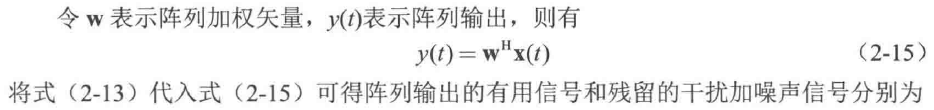

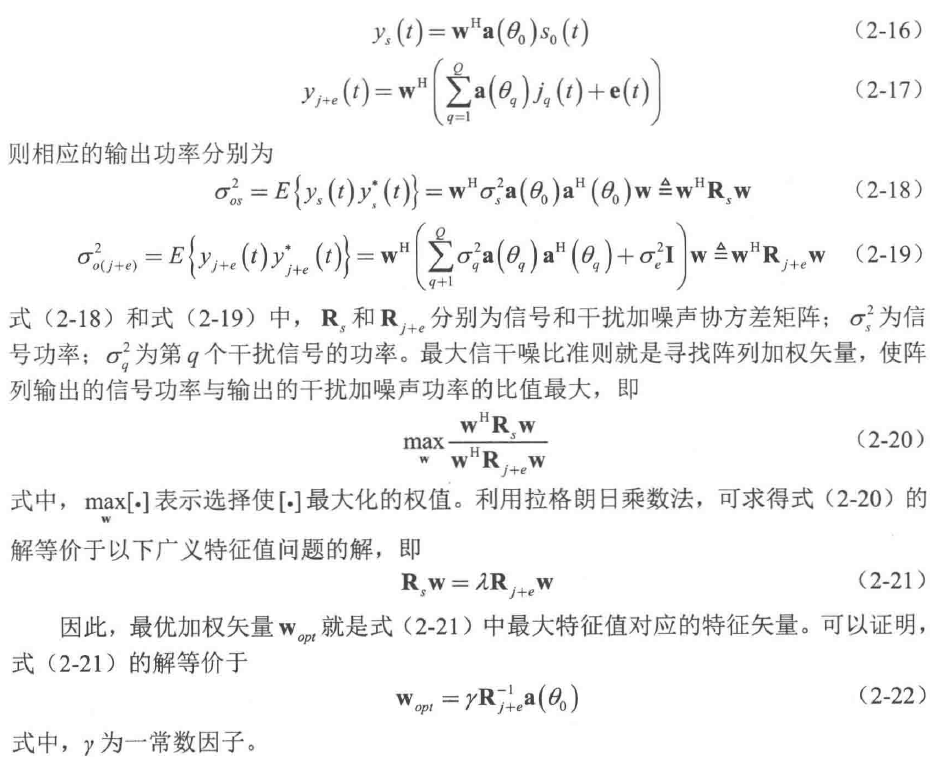

**已知:信号和干扰+噪声的协方差矩阵**

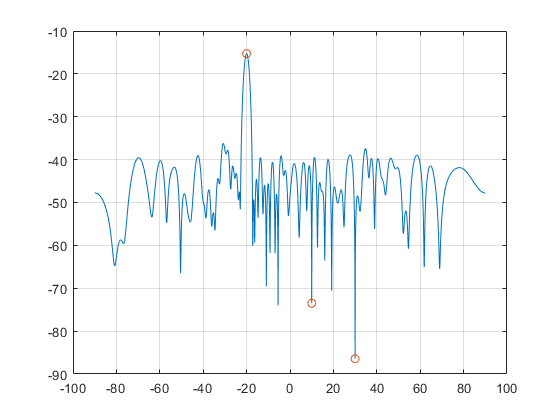

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 64;                                                                      %阵元个数
theta = [-20 10 30];                                                        %信号 干扰 干扰
M = numel(theta);                                                           %信源个数
snr = 10;                                                                   %信噪比
K = 1024;                                                                   %采样点数

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形

%--------------------------------------------------------------------------
%   接收信号为随机值
%   并按照阵列流形构造回波相位                                  
%--------------------------------------------------------------------------
S = randn(M,K) + 1j.*randn(M,K);                                            %构建接收信号

%--------------------------------------------------------------------------
%   构建干扰信号的协方差矩阵
%--------------------------------------------------------------------------
X = A(:,end-M+2:end)*S(end-M+2:end,:);                                                      %对干扰信号构造协方差矩阵
X1 = awgn(X,snr,'measured');

%--------------------------------------------------------------------------
%   最优导向矢量w_opt为R_jn中最大特征值对应的特征向量，即为
%   w_opt = y*R_jn^-1*a(theta_0)
%--------------------------------------------------------------------------
R_jn = X1*X1';                                                              %协方差矩阵
w_opt = R_jn^-1*(taylorwin(N).*A(:,1));                                                     %用干扰的逆 * 信号来向的阵列流形构造 导向矢量


%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
idx = 1;
for theta_d = -90:0.1:90
    A1 = exp(1j.*2*pi*d.'*sind(theta_d));
    output(idx) = w_opt'*A1;
    idx = idx + 1;
end

%--------------------------------------------------------------------------
%   计算 信号 干扰角度
%--------------------------------------------------------------------------
for idx = 1:length(theta)
    index(idx) = find([-90:0.1:90]==theta(idx));
end

figure(1)
plot(-90:0.1:90,db(abs(output)));grid on;hold on
plot(theta,db(abs(output(index))),'o');
hold off